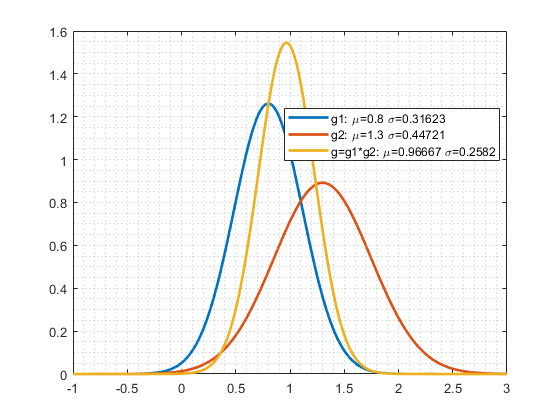

clear variables; close all; clc;

% distribution of a product of gaussian random variables
% answer: a gaussian distribution if properly scaled (normalized)

% parameters
mu1 = 0.8;
sigma1 = sqrt(0.1);
mu2 = 1.3;
sigma2 = sqrt(0.2);
normalize_factor = sigma1^2 + sigma2^2;
scale_factor1 = sigma2^2/normalize_factor;
scale_factor2 = sigma1^2/normalize_factor;
mu = scale_factor1*mu1+scale_factor2*mu2;
sigma = sqrt(sigma1^2*sigma2^2/normalize_factor);
xstart = min([mu1 mu2 mu])-5*max([sigma1 sigma2 sigma]);
xend = max([mu1 mu2 mu])+5*max([sigma1 sigma2 sigma]);
dx = 1e-4;
x = xstart:dx:xend;

% pdfs
g1 = normpdf(x,mu1,sigma1);
g2 = normpdf(x,mu2,sigma2);
g = normpdf(x,mu,sigma);

% plot
figure
plot(x,g1,'LineWidth',2,'DisplayName',['g1: \mu=' num2str(mu1) ' \sigma=' num2str(sigma1)])
hold on; grid minor;
plot(x,g2,'LineWidth',2,'DisplayName',['g2: \mu=' num2str(mu2) ' \sigma=' num2str(sigma2)])
plot(x,g,'LineWidth',2,'DisplayName',['g=g1*g2: \mu=' num2str(mu) ' \sigma=' num2str(sigma)])
legend('location','best')
xlim([-1 3])